% Differential equation to transfer function.

% Setup
syms s; clf; 

% Transfer function.
H = (s+1)/(s^3+3*s^2+3*s+2); 

% Different model representations
TF = ELAB.TF(H) % TF model.

TF =
 
          s + 1
  ---------------------
  s^3 + 3 s^2 + 3 s + 2
 
Continuous-time transfer function.



SS = ELAB.SS(H) % State-space model.

SS =
 
  A = 
         x1    x2    x3
   x1    -3  -1.5    -1
   x2     2     0     0
   x3     0     1     0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
        x1   x2   x3
   y1    0  0.5  0.5
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



ZP = ELAB.ZP(H) % Zero-pole-gain model.

ZP =
 
         (s+1)
  -------------------
  (s+2) (s^2 + s + 1)
 
Continuous-time zero/pole/gain model.




% Information on the models.
size(TF)

Transfer function with 1 outputs and 1 inputs.


isstable(TF)

ans = logical
   1


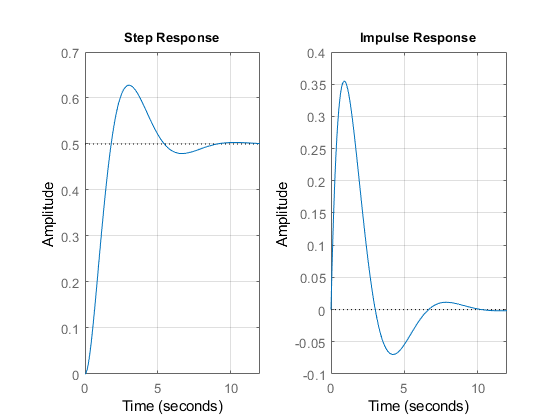


% Visualization.
subplot(1,2,1); step(TF); grid;
subplot(1,2,2); impulse(TF); grid; clf;

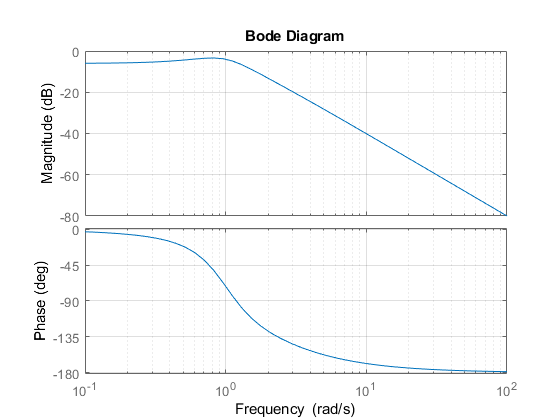

bode(TF); grid;

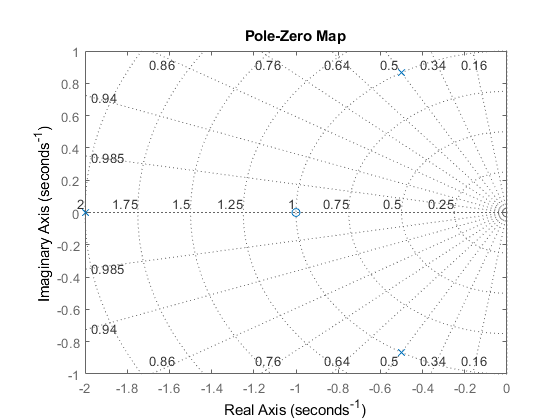

pzplot(TF); grid;

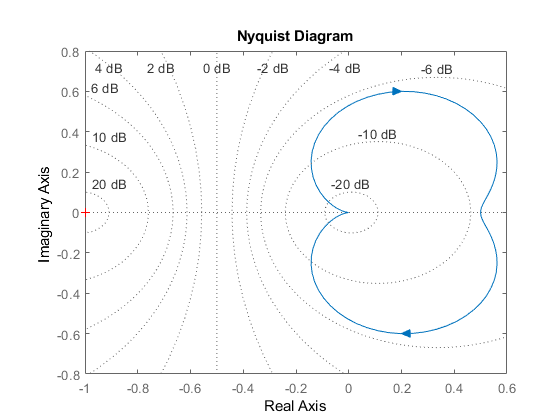

nyquist(TF); grid;

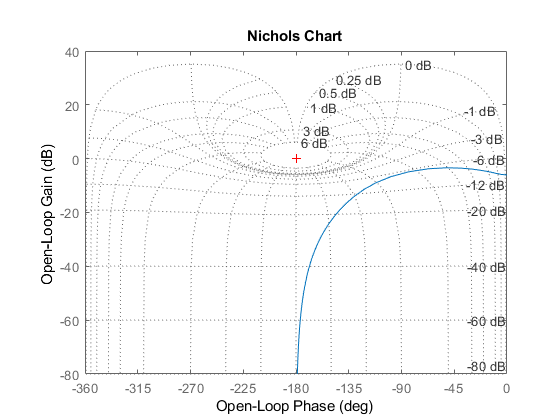

nichols(TF); grid;

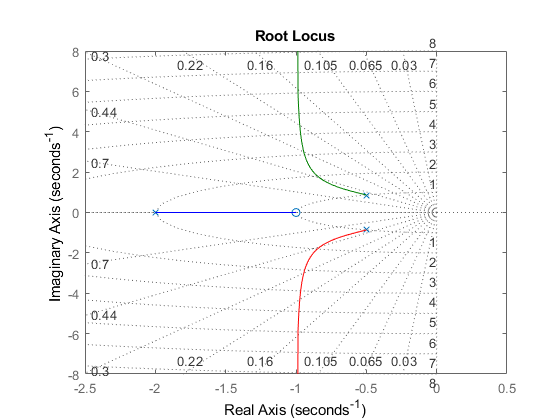

rlocus(TF); grid;